# Degradation Curves

Use this file to

- view the curves

- accelerate them

- alter them

- save them

load Q_degradation.csv
load R0_degradation.csv
% motor deg is derived below

## Plot the curves

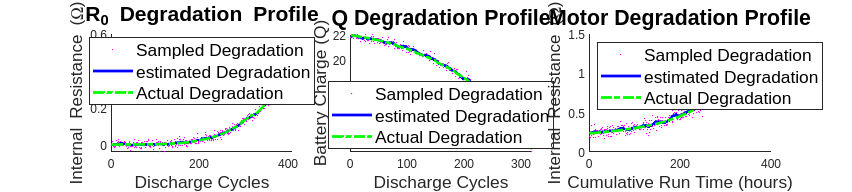

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.48], R0_degradation);
rdegr = normrnd(rdeg, .013);
restr = movmean(rdegr, 22);

frdeg = figure("Name", "rdeg"); clf;
frdeg.Position = [0 0 1600 360];
subplot(1,3,1);
hold on;
plot(rdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(restr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(rdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);


qdeg = interp1([Q_degradation(1) Q_degradation(end)], [22 13], Q_degradation);
qdegr = normrnd(qdeg, .2);
qestr = movmean(qdegr, 10);
subplot(1,3,2);
% fqdeg = figure("Name", "qdeg"); clf;
% fqdeg.Position = [0 0 800 400];
hold on;
plot(qdegr, 'm.', 'markersize', 1, "DisplayName", "Sampled Degradation");
plot(qestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(qdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
x = -15:.05:05;
y = atan(x/5)/7;
mdeg = interp1([y(1) y(end)], [.2371 1.2], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
subplot(1,3,3);
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'northwest', 'fontsize', 13);

## Convert from cycles to runtime

p = polyfit([412:-1:1], rdeg, 3)

p =    -0.0000    0.0000   -0.0044    0.4568


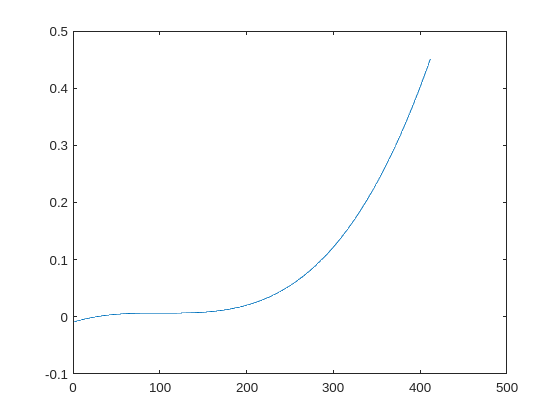

res = polyval(p, [412:-1:1]);
f2 = figure(2); clf;
f2.Position = [0 0 600 600];
set(gcf, 'Resize', 'off')
plot(res)

f3 = figure(3); clf;
f3.Position = [0 0 600 600]
plot([1:1:20])


## Save the curves

save('params\rdeg.mat', 'rdeg');
save('params\qdeg.mat', 'qdeg');
save('params\mdeg.mat', 'mdeg');

## Downsample the curve (artificial acceleration)

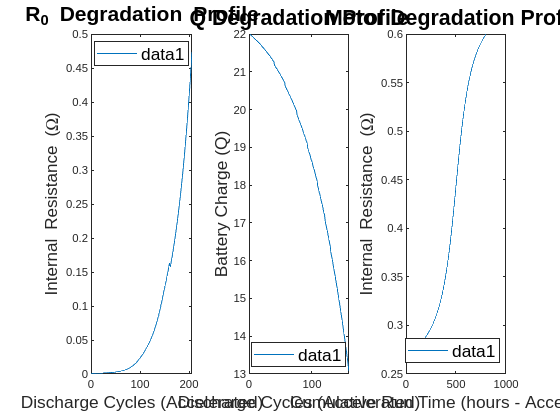

rdown = downsample(rdeg, 2);
qdown = downsample(qdeg, 2);
%mdown = downsample(mdeg, 2)';
%rdown = rdeg;
mdown = mdeg';

f2 = figure(2); clf;
f2.Position = [0 0 1200 300];
subplot(1,3,1);
plot(rdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);
subplot(1,3,2);
plot(qdown);
xlabel("Discharge Cycles (Accelerated)",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);
subplot(1,3,3);
plot(mdown);
xlabel("Cumulative Run Time (hours - Accelerated)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);

## Save the accelerated curves

save('degradation\rdeg.mat', 'rdeg');
save('degradation\qdeg.mat', 'qdeg');
save('degradation\mdeg.mat', 'mdeg');

save('degradation\rdown.mat', 'rdown');
save('degradation\qdown.mat', 'qdown');
save('degradation\mdown.mat', 'mdown');

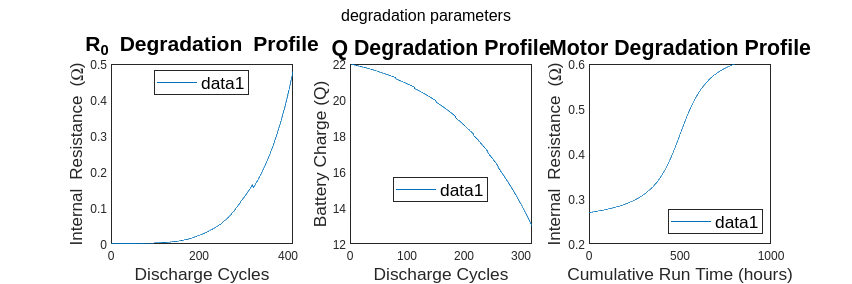

f3 = figure("name", "deg"); clf;
f3.Position = [0 0 1200 400];
subplot(1,3,1);
plot(rdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Internal Resistance (\Omega)",  'fontsize', 13);
title("R_0 Degradation Profile", 'fontsize', 16);
legend('location', 'best',  'fontsize', 13);

subplot(1,3,2);
plot(qdeg);
xlabel("Discharge Cycles",  'fontsize', 13);
ylabel("Battery Charge (Q)",  'fontsize', 13);
title("Q Degradation Profile", 'fontsize', 16);
legend('Location', 'best',  'fontsize', 13);

subplot(1,3,3);
plot(mdeg);
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'southeast', 'fontsize', 13);
sgtitle('degradation parameters');

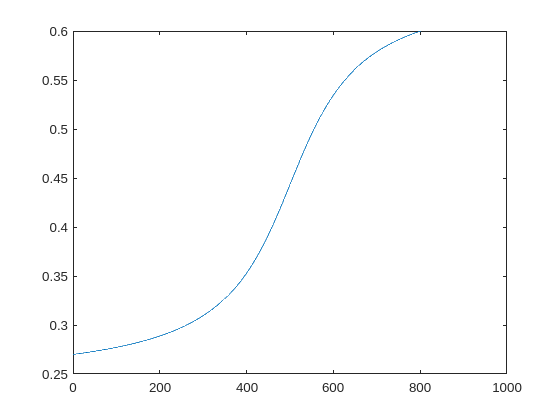

f5 = figure(5); clf;
plot(mdeg)

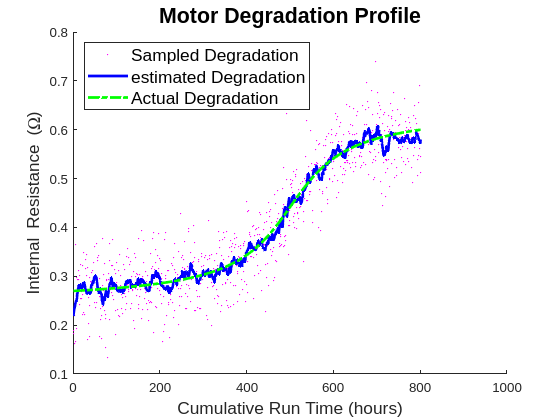

f1 = figure(1); clf;
f1.Position = [0 0 900 400];
x = -25:.05:15;
coef = [1/20 1/5];
y = coef(1)*atan(coef(2)*x);
mdeg = interp1([y(1) y(end)], [.27 .6], y);
mdegr = normrnd(mdeg, .05);
mestr = movmean(mdegr, 15);
% fmdeg = figure("Name", "mdeg"); clf;
% fmdeg.Position = [0 0 800 400];
hold on;
plot(mdegr, 'm.', 'markersize', 3, "DisplayName", "Sampled Degradation");
plot(mestr, 'b', 'linewidth', 2, "DisplayName", "estimated Degradation");
plot(mdeg, 'g-.', 'linewidth', 2, "DisplayName", "Actual Degradation");
hold off;
xlabel("Cumulative Run Time (hours)", 'fontsize', 13);
ylabel("Internal Resistance (\Omega)", 'fontsize', 13);
title("Motor Degradation Profile", 'fontsize', 16);
legend('location', 'northwest', 'fontsize', 13);

length(x)

ans = 801

24*length(x)

ans = 19224

motor_max_amp_hrs = 100*length(x)/8

motor_max_amp_hrs = 1.0013e+04

length(mdeg)

ans = 801

x2 = [0:12.5:motor_max_amp_hrs-1];

length(x2)

ans = 801

p = polyfit(x2, mdeg, 8);

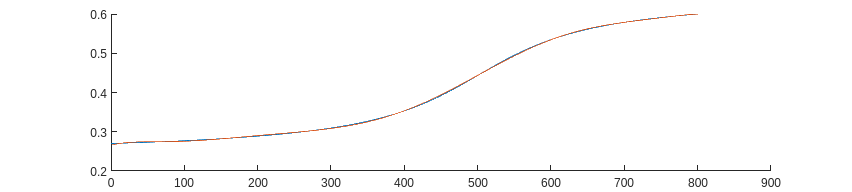

y2 = polyval(p, x2);
f2 = figure(2); clf;
f2.Position = [0 0 1200 600];
hold on;
plot(mdeg);
plot(y2(1:end));
hold off;

p

p =    -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.2660


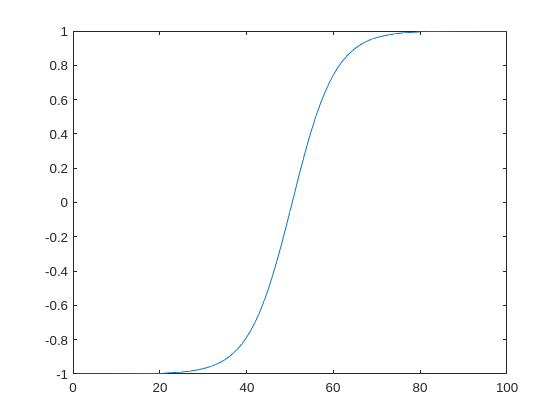

%% Initialize
x = linspace(-10,10);

%% Sigmoid
s = (1-exp(-x))./(1+exp(-x));
figure; clf; plot(s);

exp(-x)

ans = 1.0e+04 *

    2.2026    1.7997    1.4705    1.2015    0.9817    0.8022    0.6554    0.5355    0.4376    0.3575    0.2921    0.2387    0.1950    0.1594    0.1302    0.1064    0.0869    0.0710    0.0580    0.0474    0.0387    0.0317    0.0259    0.0211    0.0173    0.0141    0.0115    0.0094    0.0077    0.0063    0.0051    0.0042    0.0034    0.0028    0.0023    0.0019    0.0015    0.0012    0.0010    0.0008    0.0007    0.0006    0.0005    0.0004    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001


f1 = figure(1); clf;
f1.Position = [0 0 900 400];
x = 0:.0001:10;
coef = [1/20 1/5];
y = coef(1)*atan(coef(2)*x2);

mdeg = interp1([y(1) y(end)], [0 1], y);
% hold on;
plot(mdeg);
% coef = [1/7 1/6];
% y = coef(1)*atan(coef(2)*x2);
% mdeg = interp1([y(1) y(end)], [0 1], y);
% plot(mdeg);
% hold off;

length(x)

ans = 100001

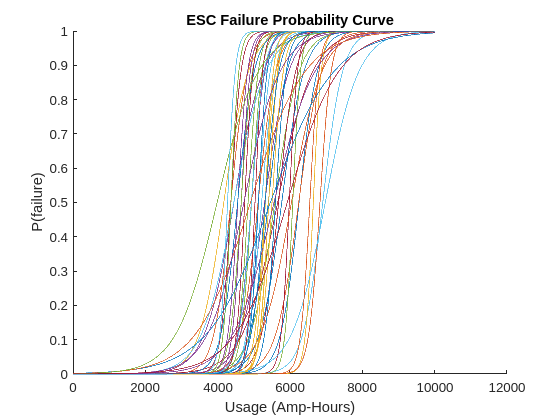

Y = [];
M = [];
for i = 1:50
    x2 = round(25 + (75-25)*abs(normrnd(35, 15))/100);
    x1 = x2 - 100;
    x = x1:.01:x2;
    c = .05 + (1-.05)*rand;
    y = atan(c*x);
    mdeg = interp1([y(1) y(end)], [0 1], y);
    X = 1:1:10001;
    [Qpre, p, sm, varcov] = fit_logistic(X, mdeg);
    M = [M; p];
end
clf;
hold on;
for i = 1:50
    res = 1./(1 + exp(-M(i,3)*1.1*(X-M(i,1)*.95)));
    %plot(X, res, 'b', 'linewidth', 3, 'displayname', 'P(failure|usage)');
    plot(X, res, 'displayname', 'P(failure|usage)');
    %xline(5800, 'r--', 'linewidth', 3);
    %plot([5794 5794], [0 res(5780)], 'm', 'linewidth', 2, 'displayname', 'Usage');
    %plot([0 5800], [res(5800) res(5800)], 'k--', 'linewidth', 2, 'displayname', 'P(failure)');
    %plot(5790, res(5800), 'm.', 'markersize', 27, 'HandleVisibility','off');
    %plot([0 6400], [res(6400) res(6400)] , 'c-.', 'linewidth', 2, 'displayname', 'random sample (no failure)')
    %plot([0 5400], [res(5400) res(5400)] , 'm-.', 'linewidth', 2, 'displayname', 'random sample (failure)')
    %break;
end
hold off;
% legend(location='best' )
title('ESC Failure Probability Curve');
ylabel("P(failure)");
xlabel("Usage (Amp-Hours)");

%xlim([4000 8000])

model = M(13,:)

model = 1.0e+03 *

    7.2690    0.0010    0.0000


age = 4400;
P_f = get_failure_prob(age, model)

P_f = 1.0521e-04

results = zeros(10000,1);
for i = 1:length(results)
    if rand < P_f
        results(i) = 1;
    end
end
sum(results)/10000

ans = 3.0000e-04

rand

ans = 0.4509

figure; clf; 
x = -88:.01:12;
x2 = 1:1:10001;
y = atan(1*x);
mdeg = interp1([y(1) y(end)], [0 1], y);
[Qpre, p, sm, varcov] = fit_logistic(x2, mdeg);

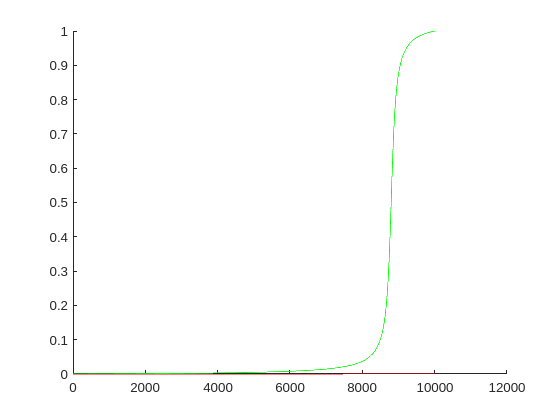

res = 1./(1 + exp(-p(3)*1.1*(x2-p(1)*.95)));
hold on;
plot(x2, res, 'r');
plot(x2, mdeg, 'g');
hold off;

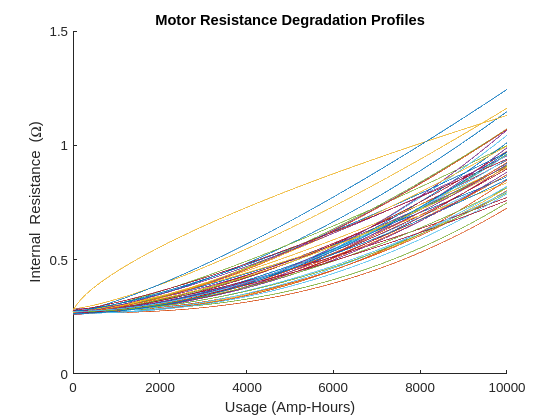

Y = [];
for i = 1:50
    m = x2 / normrnd(13000, 1200);
        e = normrnd(1.7, .3);
    b = normrnd(.27, .005);
    y = m.^e+b;
    Y = [Y; y];
end

clf;
hold on;
for i = 1:50
    plot(x2, Y(i,:));
end
ym = (x2/12600).^1.58 + .27;
%plot(x2, ym, 'r-', 'LineWidth', 3, 'DisplayName', 'Model');
hold off;
ylim([0 1.5]);
xlim([0 10000]);
title('Motor Resistance Degradation Profiles');
ylabel("Internal Resistance (\Omega)");
xlabel("Usage (Amp-Hours)");



M = [];
for i = 1:50
    p = polyfit(x2, Y(i,:), 2);
    M = [M; p];
end

polyval(M(10,:), 9000)

ans = 0.8225

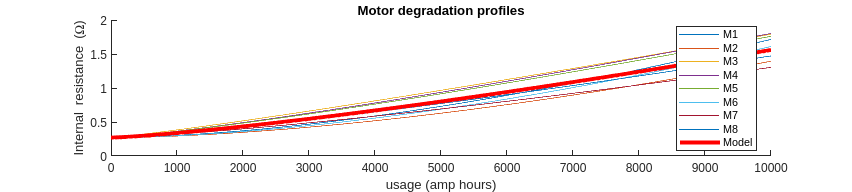

f3 = figure(3); clf;
f3.Position = [0 0 800 1200];
hold on;
y1 = (x2/8000).^1.65 + .27;
y2 = (x2/9300).^1.64 + .268;
y3 = (x2/6900).^1.13 + .271;
y4 = (x2/7000).^1.2 + .269;
y5 = (x2/7200).^1.21 + .272;
y6 = (x2/8400).^1.68 + .27;
y7 = (x2/9740).^1.29 + .269;
y8 = (x2/8643).^1.26 + .27;
ym = (x2/8200).^1.28 + .27;

plot(x2, y1, 'DisplayName', 'M1');
plot(x2, y2, 'DisplayName', 'M2');
plot(x2, y3, 'DisplayName', 'M3');
plot(x2, y4, 'DisplayName', 'M4');
plot(x2, y5, 'DisplayName', 'M5');
plot(x2, y6, 'DisplayName', 'M6');
plot(x2, y7, 'DisplayName', 'M7');
plot(x2, y8, 'DisplayName', 'M8');
plot(x2, ym, 'r-', 'LineWidth', 3, 'DisplayName', 'Model');
legend('location', 'best');
title("Motor degradation profiles");
xlabel("usage (amp hours)");
ylabel("Internal resistance (\Omega)")
hold off;

deg = 2;
p1 = polyfit(x2, y1, deg);
yp1 = polyval(p1, x2);

p2 = polyfit(x2, y2, deg);
yp2 = polyval(p2, x2);

p3 = polyfit(x2, y3, deg);
yp3 = polyval(p3, x2);

p4 = polyfit(x2, y4, deg);
yp4 = polyval(p4, x2);

p5 = polyfit(x2, y5, deg);
yp5 = polyval(p5, x2);

p6 = polyfit(x2, y6, deg);
yp6 = polyval(p6, x2);

p7 = polyfit(x2, y7, deg);
yp7 = polyval(p7, x2);

p8 = polyfit(x2, y8, deg);
yp8 = polyval(p8, x2);

pm = polyfit(x2, ym, deg);
ypm = polyval(pm, x2);


polyval(pm, 8000)

ans = 1.2355

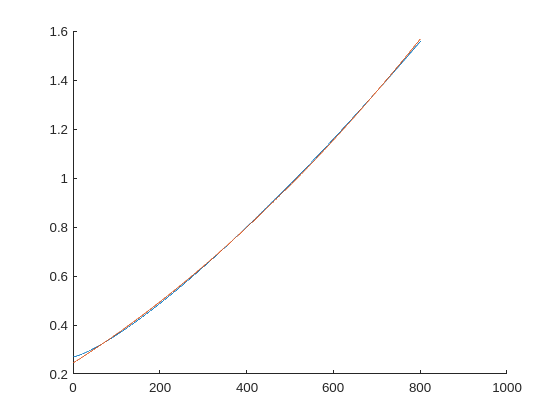

f6 = figure(6); clf;
hold on;
plot(ym);
plot(ypm);
hold off;

p1

p1 =     0.0000    0.0000    0.2482


p2

p2 =     0.0000    0.0000    0.2555


p3

p3 =     0.0000    0.0001    0.2524


p4

p4 =     0.0000    0.0001    0.2442


p5

p5 =     0.0000    0.0001    0.2473


p6

p6 =     0.0000    0.0000    0.2511


p7

p7 =     0.0000    0.0001    0.2493


p8

p8 =     0.0000    0.0001    0.2480


uav.motors(1).r_coef = p1;
uav.motors(2).r_coef = p2;
uav.motors(3).r_coef = p3;
uav.motors(4).r_coef = p4;
uav.motors(5).r_coef = p5;
uav.motors(6).r_coef = p6;
uav.motors(7).r_coef = p7;
uav.motors(8).r_coef = p8;

save('estimation/mestcoef.mat', 'pm')


x = [0:22:7018]

x =            0          22          44          66          88         110         132         154         176         198         220         242         264         286         308         330         352         374         396         418         440         462         484         506         528         550         572         594         616         638         660         682         704         726         748         770         792         814         836         858         880         902         924         946         968         990        1012        1034        1056        1078


length(x)

ans = 320

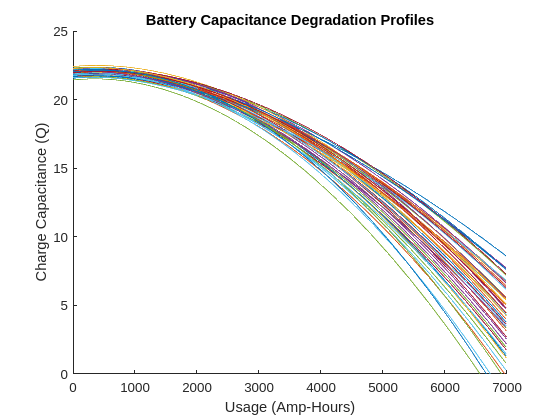

Y = [];
for i = 1:50
    m = 1 / normrnd(1300, 50);
    e = normrnd(1.8, .075);
    m2 = normrnd(2000, 125);
    b = normrnd(21.95, .25);
    y = -(m*x).^e + (x/m2) + b;
    Y = [Y; y];
end

clf;
hold on;
for i = 1:50
    plot(x, Y(i,:));
end
hold off;
ylim([0 25]);
xlim([0 7000]);
title('Battery Capacitance Degradation Profiles');
ylabel("Charge Capacitance (Q)");
xlabel("Usage (Amp-Hours)");


M = [];
for i = 1:50
    p = polyfit(x, Y(i,:), 2);
    M = [M; p];
end

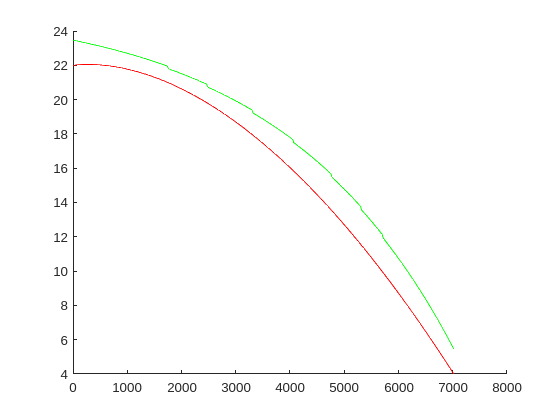

ans = 18.5181

qdeg = interp1([Q_degradation(1) Q_degradation(end)], [22 4], Q_degradation)+2*rand;
figure; clf;
y = -(x/1300).^1.8 + x/2500 + 22;
hold on;
plot(x,y, 'r');
plot(x, qdeg, 'g');
hold off;

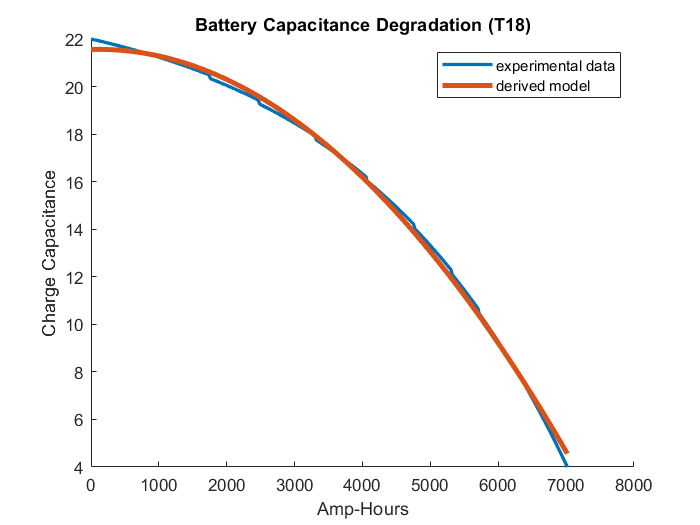

f1 = figure(1); clf;
y = polyval(p, x);
hold on;
plot(x,qdeg, 'DisplayName', 'experimental data', 'LineWidth', 2);
plot(x,y, 'DisplayName', 'derived model', 'LineWidth', 3);
title("Battery Capacitance Degradation (T18)");
xlabel("Amp-Hours");
ylabel("Charge Capacitance")
hold off;
legend;

rdeg = interp1([R0_degradation(1) R0_degradation(end)], [.0011 0.11], R0_degradation)

rdeg =     0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011


x = [1:17:7004]

x =      1    18    35    52    69    86   103   120   137   154   171   188   205   222   239   256   273   290   307   324   341   358   375   392   409   426   443   460   477   494   511   528   545   562   579   596   613   630   647   664   681   698   715   732   749   766   783   800   817   834


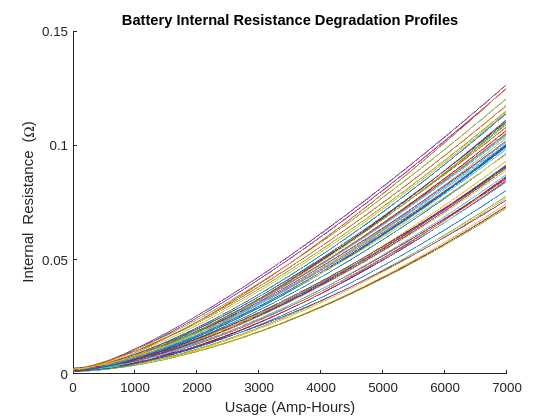


Y = [];
for i = 1:50
    m = 1 / normrnd(33500, 1000);
    e = normrnd(1.5, .1);
    b = max(.001, normrnd(.0014, .0005));
    y = (m*x).^e  + b;
    Y = [Y; y];
end

clf;
hold on;
for i = 1:50
    plot(x, Y(i,:));
end
hold off;
ylim([0 .15]);
xlim([0 7000]);
title('Battery Internal Resistance Degradation Profiles');
ylabel("Internal Resistance (\Omega)");
xlabel("Usage (Amp-Hours)");

M = [];
for i = 1:50
    p = polyfit(x, Y(i,:), 2);
    if p(3) < .0001
        p(3) = .00075 + (.0013 - .00075) * rand;
    end
    M = [M; p];
end

polyval(M(3,:), 1000)

ans = 0.0053

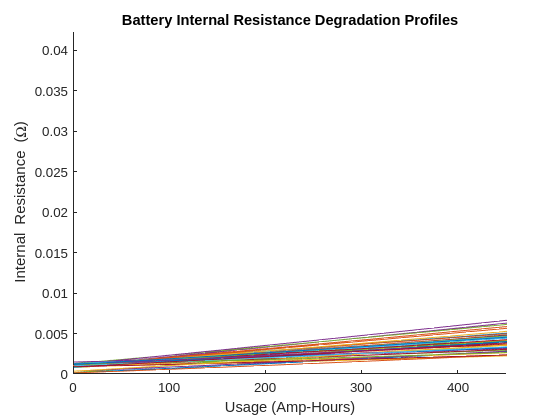

figure; clf;
hold on;
for i = 1:50
    plot(x, polyval(M(i,:), x));
end
hold off;
ylim([0 .15]);
xlim([0 7000]);
title('Battery Internal Resistance Degradation Profiles');
ylabel("Internal Resistance (\Omega)");
xlabel("Usage (Amp-Hours)");

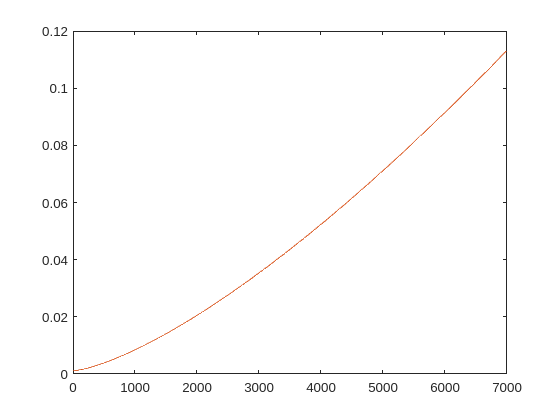

r = (x/33400).^1.4 + .0011;
plot(x,r)
%p = polyfit(x, r, 2);
%yr = polyval(p, x);
hold on;
plot(x, r);
%plot(x, yr);
hold off;

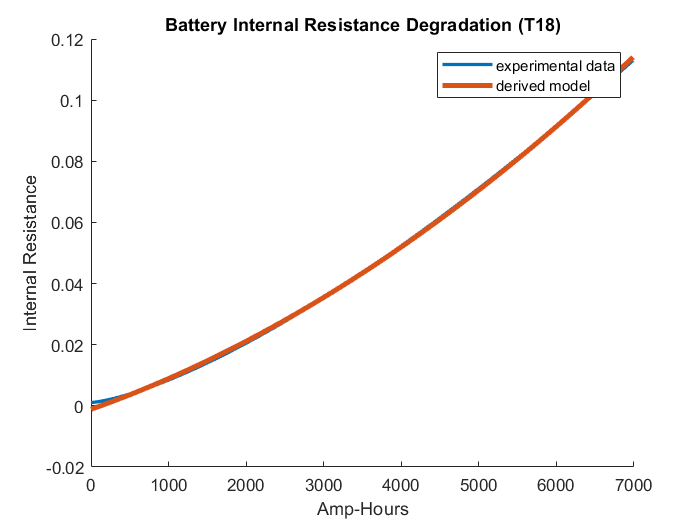

clf;
y = polyval(p, x);
%plot(x,y, "DisplayName", 'poly');
hold on;
%plot(x,r);
plot(x,r, 'DisplayName', 'experimental data', 'LineWidth', 2);
plot(x,y, 'DisplayName', 'derived model', 'LineWidth', 3);
title("Battery Internal Resistance Degradation (T18)");
xlabel("Amp-Hours");
ylabel("Internal Resistance")
legend;
hold off;

polyval(p, 2000)

ans = 0.0211

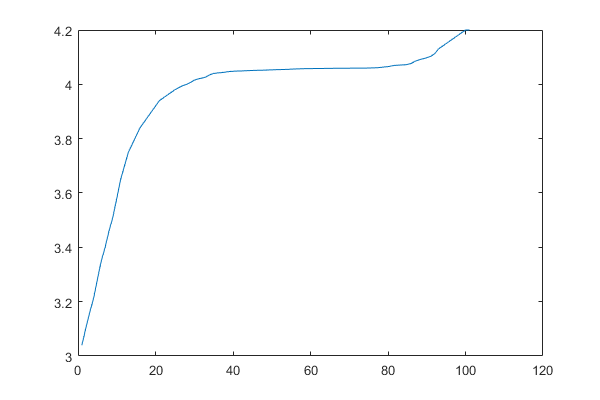

f5 = figure(5); clf;
x = [1:1:length(soc_ocv)];
plot(x, soc_ocv);

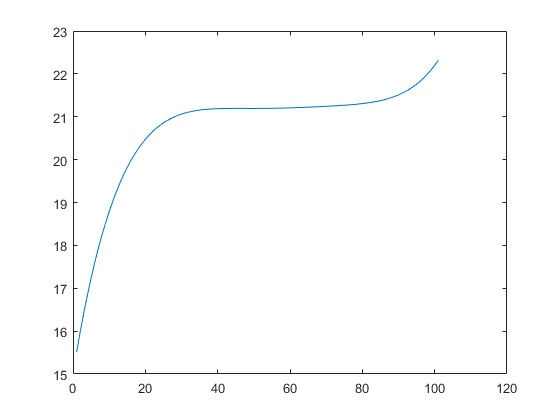

f6 = figure(6); clf;
y = polyval(z_coef, x);
plot(x,y);

[Qpre, p, sm, varcov] = fit_logistic(x2, mdeg)

Qpre =     0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003


p = 1.0e+03 *

    8.1017    0.0012    0.0000


sm =     0.1212
    0.0001
    0.0000


varcov =     0.0147    0.0000   -0.0000
    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000


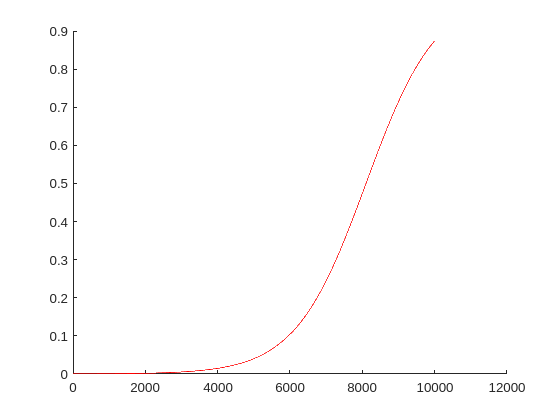

figure; clf;
hold on;
Qpos = 1./(1 + exp(-p(3)*(x2-p(1))));
plot(x2, Qpos, 'r');
hold off;

interp1([0.0 1.0],[.99 .85],.90)

ans = 0.8640


Qinf = 10.2; alpha = 0.33; thalf = 108.5;
t = 100:120;
Q = Qinf./(1 + exp(-alpha*(t-thalf)));
noise = randn(1,length(t));
Qd = Q+noise;
Qpre = fit_logistic(t,Qd);
figure(1)
clf
hold on
plot(t,Qd,'o')  % data
plot(t,Qpre)    % best fitting logisti

function [ Qpre, p, sm, varcov] = fit_logistic(t,Q)
%fit a logistic function to time series Q(t).
%   Inputs: t (time),Q (time series variable)
%   Outputs: Qpre (logistic model fit to data) and
%   p is 3 element vector containing parameters describing the logistic:
%       thalf, Qinf, and alpha
%   Q(t) = Qinf/(1 + exp(-alpha*(t-thalf)))
%       thalf is symmetric inflection point
%       Qinf is value as t --> infinity
%       alpha is time decay constant
%   sm is 3 element vector giving 1-sigma confidence limits of parameters
%       e.g., thalf = p(1) +/- sm(1)
%       simply double the values in sm to get 95% confidence limits
%   varcov is the complete 3x3 variance-covariance matrix for investigating
%       how model paramters co-vary with each other.
%       sm is sqrt(diag(varcov))
%
%   Example:
%       Qinf = 10.2; alpha = 0.33; thalf = 108.5;
%       t = 100:120;
%       Q = Qinf./(1 + exp(-alpha*(t-thalf)));
%       noise = randn(1,length(t));
%       Qd = Q+noise;
%       Qpre = fit_logistic(t,Qd);
%       figure(1)
%       clf
%       hold on
%       plot(t,Qd,'o')  % data
%       plot(t,Qpre)    % best fitting logistic
%       
% Written by James Conder, Southern Illinois University, Oct. 2010
% Cleaned up for publishing May 16, 2013
%   May 17, 2013: Allow for decreasing logistic.
%   May 23, 2013: Fix instability when using short 
%       or long absolute times (relative to alpha = 1).
%   May 28, 2013: added example in comments, fixed an introduced bug
%       from May 23 edit. 
%   Feb 12, 2014: Revisited occasional flatlining problem.
%       (Qpre goes to mean).
%       Made initial alpha more robust. Scaled to time rather than simply
%       defaulting to one (removes much of need for rescaling time).
%       Added check for flatlining. If occurs, reset seeds with larger
%       alpha and start over.
%   Jan 25, 2016: calculate confidence limits for parameters
% equations are set up to solve for an increasing logistic.
% Check if decreasing and if so, reverse time
[~,I] = sort(t);
reverse_t = false;
if sum(diff(Q(I))) < 0      % decreasing in time
    reverse_t = true;
    t = -t;
end
% stretch short or long sequences in time to stabilize alpha
tstretch = [];
if max(t)-min(t) < 1.e-4 || max(t)-min(t) > 1e5;
    tstretch = 1./(max(t) - min(t));
    t = t*tstretch;
end
% initial guesses for parameters
thalf = 0.5*(min(t) + max(t));
Qinf = max(Q);
alpha = 1./(max(t)-min(t)); alphareset = alpha;
flipQ = false;
if isrow(Q)
    flipQ = true;   % expecting a column vector. flip if row.
    t = t';
    Q = Q';
end
itermax = 1000 ;	% number of maximum iterations
epsilon = 1;
ii = 0 ;            % initialize counter
thresh = 1.e-6 ;    % threshold to stop iterating
G = zeros(length(t),3) ;    % dimensionalize partial derivative matrix
while epsilon > thresh
  ii = ii + 1 ;
  Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;  % 'predicted' data
  if max(Qpre) - min(Qpre) == 0
      % if Qpre flatlines, "a" likely needed to be seeded higher
      % (sharper climb)
      alphareset = 2*alphareset;
      thalf = 0.5*(min(t) + max(t));
      Qinf = max(Q);
      alpha = alphareset;      
      Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;
  end
  d = Q - Qpre ;      % data vector (predicted - observed)
  % linearized partial derivatives
  ee = min(exp(-alpha*(t-thalf)),1.e12) ;
  eee = 1./((1 + ee).^2) ;
  G(:,1) = -Qinf*alpha*(ee.*eee) ;          % dd/dthalf
  G(:,2) = 1./(1 + ee) ;                % dd/dQinf
  G(:,3) = Qinf*(t-thalf).*(ee.*eee) ;  % dd/dalpha
  
  [U,S,V] = svd(G,0);				% Singular Value Decomposition
  Sinvdiag = 1./diag(S) ;
  ising = Sinvdiag(1)./Sinvdiag < 1.e-12 ;
  Sinvdiag(ising) = 0;
  Sinv = diag(Sinvdiag);
  dm = 0.1*V*Sinv*U'*d;
							  
  % get new parameters: m = m0 + dm
  thalf = thalf + dm(1);
  Qinf = Qinf + dm(2);
  alpha = alpha + dm(3);				 
							   				  
  epsilon = norm(dm);
  if ii > itermax
	    disp('max number of iterations reached...exiting')
        disp(['normalized epsilon: ' num2str(epsilon/thresh)]) 
        epsilon = thresh ;
  end
end
Qpre = Qinf./(1 + exp(-alpha*(t-thalf))) ;  % 'predicted' data
if ~isempty(tstretch)
    thalf = thalf/tstretch;
    alpha = alpha*tstretch;
end  
if reverse_t        % decreasing logistic
    thalf = -thalf;
    alpha = -alpha;
end
if flipQ
    Qpre = Qpre';
    Q = Q';     % necessary for a posteriori variance 
end
p = [ thalf Qinf alpha ];
%%% find confidence bounds for parameters (1-sigma)
if nargout > 2
    sd = sum((Q-Qpre).^2)/(length(Q)-3);       % a posteriori variance
    varcov = sd*sd*inv(G'*G);   % model variance-covariance matrix
    sm = sqrt(diag(varcov));    % model variance
end
end









